Matlab code for the Course: **Modelling and Simulation Mechatronics System (2020)**

by Enrico Bertolazzi and Francesco Biral

Dipartimento di Ingegneria Industriale

Università degli Studi di Trento

email: [enrico.bertolazzi@unitn.it](mailto:enrico.bertolazzi@unitn.it)

#### Initialize by cleaning memory and widows

close all;

#### Initialize parameters of the model and instantiate model class

gravity = 9.81; % degree
ODE     = ParabolicPendulum( gravity );

#### Initialize the solver class

solver = Heun();
solver.setODE( ODE );

#### Advance the ODE

DT = 0.1;
T  = 10;
x0 = 0;
y0 = 1;
u0 = 2;
v0 = 0;
lambda0 = gravity/4-6;
%Zini = [ 0, 0, 1, 0, 0]; % x, y, u, v, lambda 
Zini = [ x0, y0, u0, v0, lambda0]; % x, y, u, v, lambda 


tt0 = 0:DT:T;
tt1 = 0:DT/10:T;
tt2 = 0:DT/100:T;
Z0 = solver.advance( tt0, Zini);
Z1 = solver.advance( tt1, Zini);
Z2 = solver.advance( tt2, Zini);

#### Plot solution

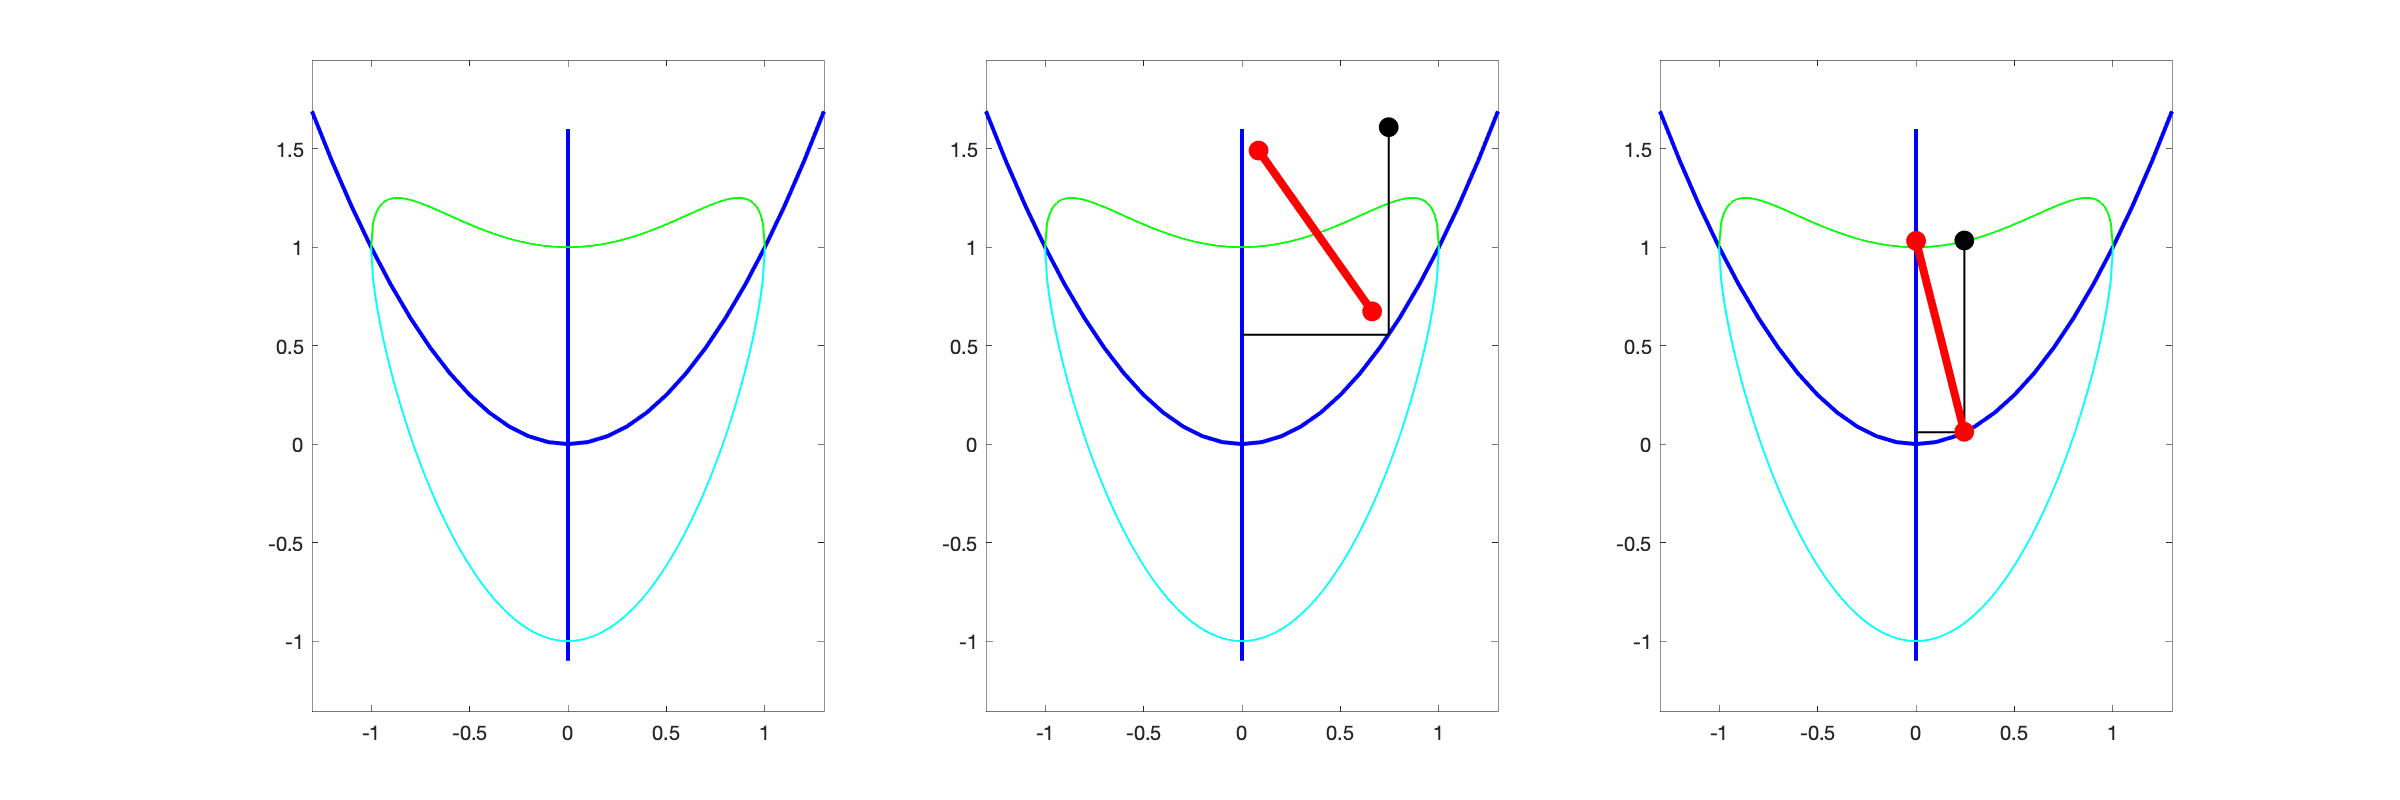

figure('Renderer', 'painters', 'Position', [10 10 1200 400])
for k=1:length(tt0)
  k0 = k; k1 = 1+10*(k-1); k2 = 1+100*(k-1);
  subplot(1,3,1);
  ODE.plot( Z0(:,k0));
  subplot(1,3,2);
  ODE.plot( Z1(:,k1));
  subplot(1,3,3);
  ODE.plot( Z2(:,k2));
  drawnow;
end

#### Initialize the solver class

solver_P = Heun_P();
solver_P.setODE( ODE );

#### Advance the ODE

DT = 0.1;
T  = 10;
x0 = 0;
y0 = 1;
u0 = 2;
v0 = 0;
lambda0 = gravity/4-6;
%Zini = [ 0, 0, 1, 0, 0]; % x, y, u, v, lambda 
Zini = [ x0, y0, u0, v0, lambda0-0.1]; % x, y, u, v, lambda 


tt0 = 0:DT:T;
tt1 = 0:DT/10:T;
tt2 = 0:DT/100:T;
Z0 = solver_P.advance( tt0, Zini);
Z1 = solver_P.advance( tt1, Zini);
Z2 = solver_P.advance( tt2, Zini);

#### Plot solution

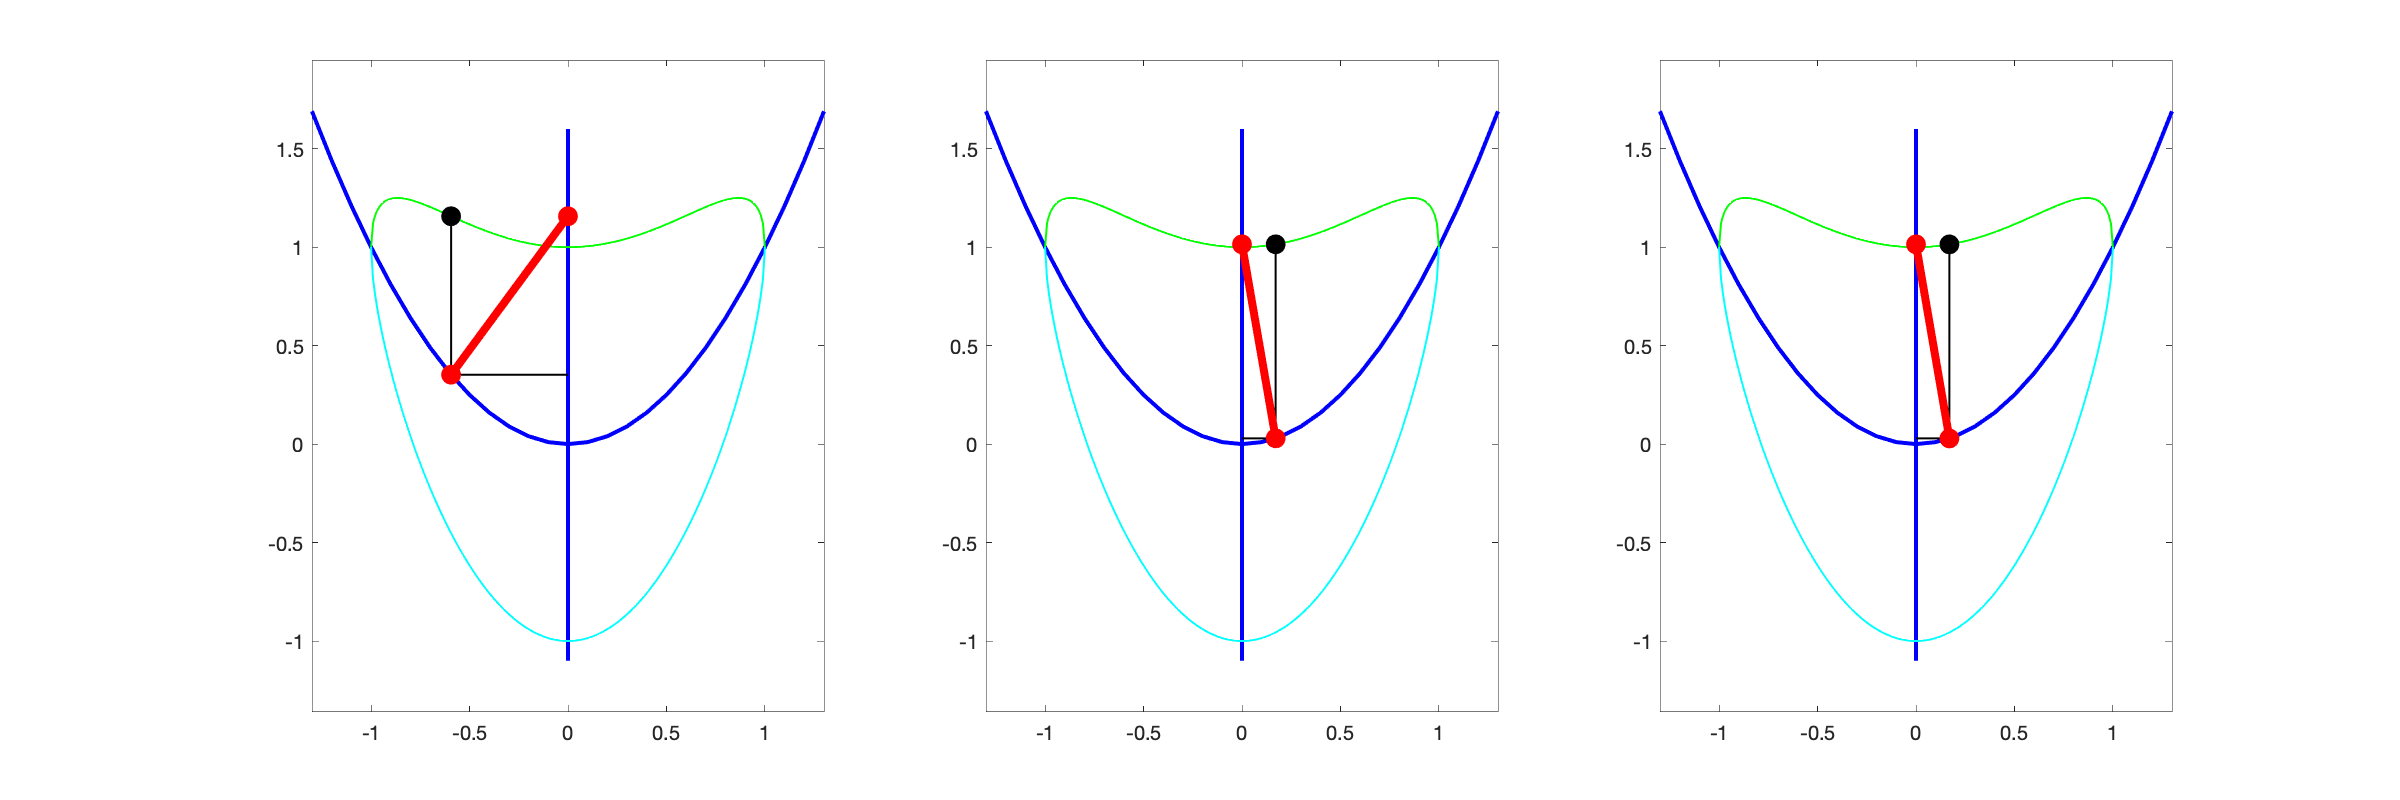

figure('Renderer', 'painters', 'Position', [10 10 1200 400])
for k=1:length(tt0)
  k0 = k; k1 = 1+10*(k-1); k2 = 1+100*(k-1);
  subplot(1,3,1);
  ODE.plot( Z0(:,k0));
  subplot(1,3,2);
  ODE.plot( Z1(:,k1));
  subplot(1,3,3);
  ODE.plot( Z2(:,k2));
  drawnow;
end